% syms s t;
s = tf('s');
student_num = [3 8 1 1 3 5 4 4];


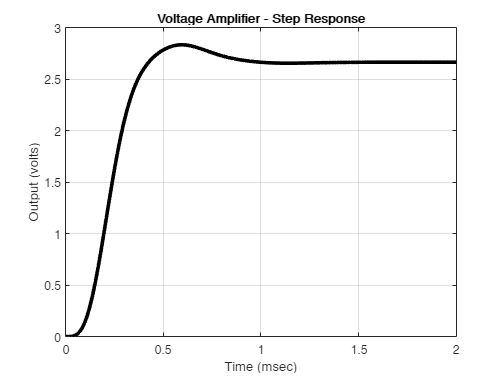

P2_ampDataPlot(38113544);

T_r   = 0.4200; %ms
T_p   = 0.597; 
T_s   = 0.81;


final_value = 2.666;
alove = final_value + final_value*0.02

alove = 2.7193

below = final_value - final_value*0.02

below = 2.6127

overshoot   = 2.835-final_value;
p_overshoot = overshoot/final_value*100;

zeta = sqrt(log(overshoot/final_value)^2/(pi^2+log(overshoot/final_value)^2));
beta = sqrt(1-zeta^2);
% beta_2 = -3*pi/log(p_overshoot)



% we want to find the zeta and the natural frequency so we can then
% approximate this curve as the step response of a 2nd order system

wn_ts = 4/(zeta*T_s);

wn_tp = pi/(T_p*beta);

wn_tr = (pi-atan(beta/zeta))/(beta*T_r);

xfer_s = wn_ts^2/(s^2+2*zeta*wn_ts*s+wn_ts^2)*final_value;
xfer_p = wn_tp^2/(s^2+2*zeta*wn_tp*s+wn_tp^2)*final_value;
xfer_r = wn_tr^2/(s^2+2*zeta*wn_tr*s+wn_tr^2)*final_value;

figure(1);
set(findall(gcf,'type','line'),'Color','Black');

[y_s, t_s] = step(xfer_s)

y_s =          0
    0.0063
    0.0244
    0.0532
    0.0917
    0.1387
    0.1933
    0.2547
    0.3218
    0.3940


t_s =          0
    0.0093
    0.0187
    0.0280
    0.0373
    0.0466
    0.0560
    0.0653
    0.0746
    0.0839


[y_p, t_p] = step(xfer_p)

y_p =          0
    0.0063
    0.0244
    0.0532
    0.0917
    0.1387
    0.1933
    0.2547
    0.3218
    0.3940


t_p =          0
    0.0100
    0.0199
    0.0299
    0.0399
    0.0498
    0.0598
    0.0698
    0.0797
    0.0897


[y_r, t_r] = step(xfer_r)

y_r =          0
    0.0063
    0.0244
    0.0532
    0.0917
    0.1387
    0.1933
    0.2547
    0.3218
    0.3940


t_r =          0
    0.0096
    0.0192
    0.0288
    0.0385
    0.0481
    0.0577
    0.0673
    0.0769
    0.0865


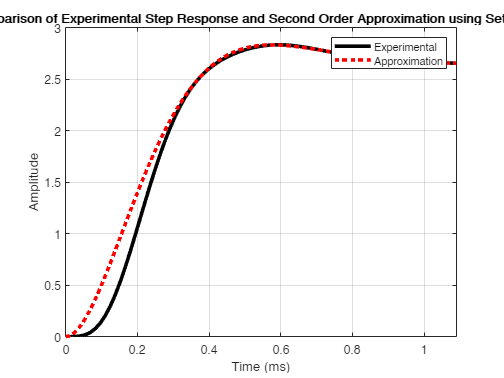


hold on
% plot(t_s, y_s, ':', 'LineWidth', 3, 'Color','Red')
% plot(t_p, y_p, ':', 'LineWidth', 3, 'Color','Black')
plot(t_r, y_r, ':', 'LineWidth', 3, 'Color','Red')
grid on
hold off

title("Comparison of Experimental Step Response and Second Order Approximation using Settle Time")
xlabel("Time (ms)")
ylabel("Amplitude")
axis([0, 1.09, 0, 3])
legend("Experimental", "Approximation")

% T_s_n = 66.5;
% overshoot_n = 16.6647-final_value;
% p_overshoot_n = overshoot_n/final_value * 100;
% zeta_n = sqrt(log(overshoot_n/final_value)^2/(pi^2+log(overshoot_n/final_value)^2));
% beta_n = sqrt(1-zeta_n^2);
% wn_ts_n = 4/(zeta_n*T_s_n);
% xfer_s_n = 1/s*wn_ts_n^2/(s^2+2*zeta_n*wn_ts_n*s+wn_ts_n^2)*final_value;
% 
% [p,x] = pzmap(xfer_s_n)
% pzmap(xfer_s_n)

[num_p2, den_p2] = tfdata(xfer_s, 'v');
